# Plan Path for Manipulator Robot Using RRT

Use the `manipulatorRRT` object to plan a path for a rigid body tree robot model in an environment with obstacles. Visualize the planned path with interpolated states. 使用 manipulatorRRT 对象在有障碍物的环境中为刚体树形机器人模型规划路径。 可视化具有插值状态的计划路径。

Load a robot model into the workspace. Use the ROCR6II manipulator arm.

clear,clc,close all;
ROCR6II = importrobot('ROCR6II_URDF_File.urdf');
ROCR6II.DataFormat = 'row';
clearCollision(ROCR6II.Bodies{1});   %删除基座的碰撞模型，对RRT有影响

Generate the environment for the robot. Create collision objects and specify their poses relative to the robot base. Visualize the environment.

为机器人生成环境，创建碰撞对象并指定它们相对于机器人基座的姿态，使环境可视化。

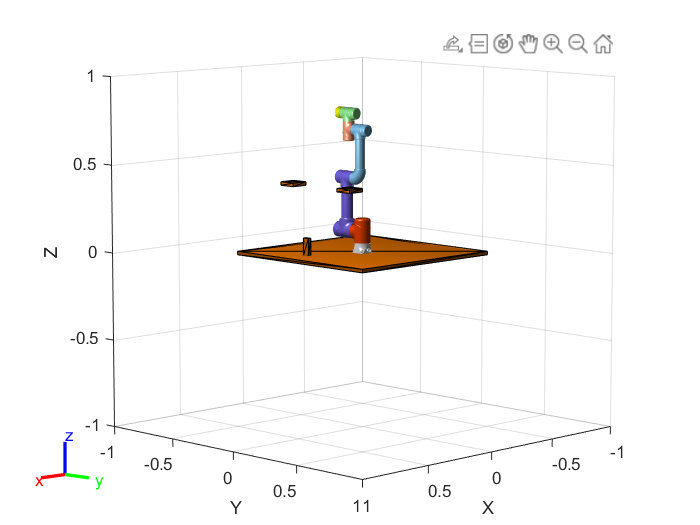

env = {collisionBox(1, 1, 0.02) collisionBox(0.1, 0.1, 0.02) collisionBox(0.02, 0.04, 0.1) collisionBox(0.1, 0.1, 0.02)}; %球形：collisionSphere()
env{1}.Pose(3, end) = 0;
env{2}.Pose(1:3, end) = [0.30 -0.25 0.40];
env{3}.Pose(1:3, end) = [0.30 -0.14 0.05];
env{4}.Pose(1:3, end) = [0.30  0.20 0.40];
homeConfig = [0 0 0 0 0 0]*pi/180;
figure1=show(ROCR6II,homeConfig,'Frames','off');
hold on
show(env{1})
show(env{2})
show(env{3})
show(env{4})

Create the RRT planner for the robot model.

为机器人模型创建RRT规划器

rrt = manipulatorRRT(ROCR6II,env);

Create the inverseKinematics solver for the robot model.

为机器人创建逆运动学解算器

ik = inverseKinematics('RigidBodyTree',ROCR6II);
tform = trvec2tform([0.25 0.05 0.2])*troty(pi);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = ROCR6II.homeConfiguration;
[configSoln,solnInfo] = ik('tool0',tform,weights,initialguess)

configSoln =     0.6457    0.3730   -2.3891    0.4452    1.5708    2.2165


solnInfo = 包含以下字段的 struct :
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0791e-09
             ExitFlag: 1
               Status: 'success'


Specify a start and a goal configuration.

指定开始和目标配置。

startConfig = [0.6457 0.3730 -2.3891 0.4452 1.5708 2.2165];
goalConfig  = initialguess;
axes = show(ROCR6II,startConfig,"Visuals","on","Collisions","off","Frames","off");
show(ROCR6II,goalConfig,"Visuals","on","Collisions","off","Frames","off");
view(130,20);
axis([-0.6,0.6,-0.6,0.6,-0.05,1]);

Plan the path. Due to the randomness of the RRT algorithm, set the `rng` seed for repeatability.

规划路径。 由于 RRT 算法的随机性，请设置 rng 种子以实现可重复性。

rng(0)
path = plan(rrt,startConfig,goalConfig);

Visualize the path. To add more intermediate states, interpolate the path. By default, the `interpolate` object function uses the value of `ValidationDistance` property to determine the number of intermediate states. The `for` loop shows every  20th element of the interpolated path.

可视化路径。 要添加更多中间状态，请插入路径。 默认情况下，interpolate 对象函数使用 ValidationDistance 属性的值来确定中间状态的数量。 for 循环显示内插路径的每 20 个元素。

interpPath = interpolate(rrt,path);
clf
for i = 1:20:size(interpPath,1)
    show(ROCR6II,interpPath(i,:),"Frames","off");
    view(130,20);
    axis([-0.6,0.6,-0.6,0.6,-0.05,1]);
    hold on
end
show(env{1})
show(env{2})
show(env{3})
%set(gcf,'outerpostion',get(0,"screensize"));
hold off

*Copyright 2021 YUXIN*